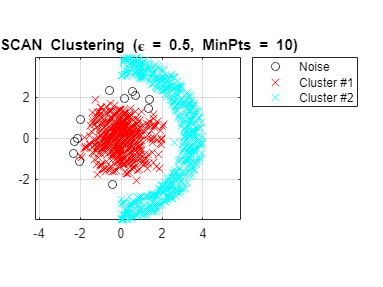

clc;
clear;
close all;
%% Load Data
data=load('mydata');
X=data.X;
%% Run DBSCAN Clustering Algorithm
epsilon=0.5;
minPts=10;
idx=DBScan(X,epsilon,minPts);
%% Plot Results
PlotClusterinResult(X, idx);
title(['DBSCAN Clustering (\epsilon = ' num2str(epsilon) ', MinPts = ' num2str(minPts) ')']);

function PlotClusterinResult(X, IDX)
    k=max(IDX);
    Colors=hsv(k);
    Legends = {};
    for i=0:k
        Xi=X(IDX==i,:);
        if i~=0
            Style = 'x';
            MarkerSize = 8;
            Color = Colors(i,:);
            Legends{end+1} = ['Cluster #' num2str(i)]; %#ok
        else
            Style = 'o';
            MarkerSize = 6;
            Color = [0 0 0];
            if ~isempty(Xi)
                Legends{end+1} = 'Noise'; %#ok
            end
        end
        if ~isempty(Xi)
            plot(Xi(:,1),Xi(:,2),Style,'MarkerSize',MarkerSize,'Color',Color);
        end
        hold on;
    end
    hold off;
    axis equal;
    grid on;
    legend(Legends);
    legend('Location', 'NorthEastOutside');
end

function [idx, isnoise] = DBScan(X,epsilon,minPts)
% Don't forget to add the license

%X = [camX,camV];
cluster_index = 0;
n=size(X,1);
idx=zeros(n,1);  
D = pairwiseDistance(X,X); % Calculate the distance between all points
label=false(n,1); % Check if a certain point has a label or not
isnoise=false(n,1); % An array to add noise points 

for i=1:n
    if(label(i) == false)
        label(i) = true;
        Neighbors = RegionQuery(i);
        if(size(Neighbors) < minPts) % If the number of points is less than the minimum points then add to noise, if not than expand the cluster
            isnoise(i) = true;
        else
            cluster_index = cluster_index + 1;
            ExpandCluster(i,Neighbors,cluster_index); % Expand Cluster
        end
    end
end

     function ExpandCluster(i,Neighbors,cluster_index)
        idx(i) = cluster_index;
        k = 1;

        while true
            j = Neighbors(k);
            
            if ~label(j)
                label(j) = true;
                Neighbors2 = RegionQuery(j);

                if numel(Neighbors2) >= minPts
                    Neighbors = [Neighbors Neighbors2]; %#ok
                end
            end

            if idx(j) == 0
                idx(j)=cluster_index;
            end
            
            k = k + 1;

            if k > numel(Neighbors)
                break;
            end
        end
    end
    
    function Neighbors=RegionQuery(i)
        Neighbors = find(D(i,:) <= epsilon);
    end
end

function Distance = pairwiseDistance(x,y)
% This function replaces the function pdist2 available only at the Machine 
% Learning toolbox. It computes the distances between rows of X.
% Author: Ana C. Goncalves
% n = norm(v) returns the Euclidean norm of vector v. This norm is also 
% called the 2-norm, vector magnitude, or Euclidean length.
    for k = 1:length(x)         
        for j = 1:length(y)      
            if k ~= j
                Distance(k,j) = norm(x(k,:) - x(j,:)); %#ok
            end
        end
    end
end